clc
clear
[audioIn,fs]=audioread("emergency/Recording (14).wav");
win=hann(1024, "periodic");
coeff=mfcc(audioIn,fs)

coeff = coeff(:,:,1) =

   -5.2110  -19.8658    1.7542   -0.9886   -0.5800   -0.5090    0.6592    0.3064    0.1266   -0.2993   -0.1844   -0.1231    0.3015    0.0209
   -5.1950  -19.4496    1.7670   -0.7015   -0.2536   -0.5939    0.6419    0.4194   -0.0608   -0.5614   -0.1434   -0.1188    0.4390   -0.0147
   -5.6187  -19.6091    1.7249   -0.5712   -0.1884   -0.6555    0.1241    0.1625    0.2247   -0.3458    0.2018    0.3545    0.3266   -0.1583
   -6.0511  -19.9461    1.4333   -0.5415   -0.2849   -0.6398   -0.2879   -0.3178   -0.1359   -0.2964    0.4302    0.5351    0.1365   -0.1080
   -5.8795  -19.8881    1.5298   -0.7446   -0.3685   -0.5399   -0.7929   -0.3534    0.3237    0.0556    0.3747    0.5824   -0.0048   -0.1243
   -5.7119  -19.9626    1.3826   -0.6425    0.1108   -0.5111   -0.8769   -0.5364    0.1016   -0.1759    0.4117    0.7459    0.2445   -0.2713
   -5.5645  -19.8426    1.7601   -0.6350   -0.0357   -0.7354   -0.8239   -0.3527   -0.0514   -0.4966    0.3598    0.4013   -0.0142


folder = fullfile(pwd);
ADS = audioDatastore(folder,'FileExtension',{'.wav','.mp4'},'IncludeSubfolders',true)

ADS =   audioDatastore with properties:

                       Files: {
                              ' .../MATLAB/Examples/R2021a/Project529/emergency/Recording (10).wav';
                              ' .../MATLAB/Examples/R2021a/Project529/emergency/Recording (11).wav';
                              ' .../MATLAB/Examples/R2021a/Project529/emergency/Recording (12).wav'
                               ... and 102 more
                              }
                     Folders: {
                              ' .../jeffinjohnson/Documents/MATLAB/Examples/R2021a/Project529/emergency'
                              }
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'
                      Labels: {}
      SupportedOutputFormats: ["wav"    "flac"    "ogg"    "mp4"    "m4a"]
         DefaultOutputFormat: "wav"


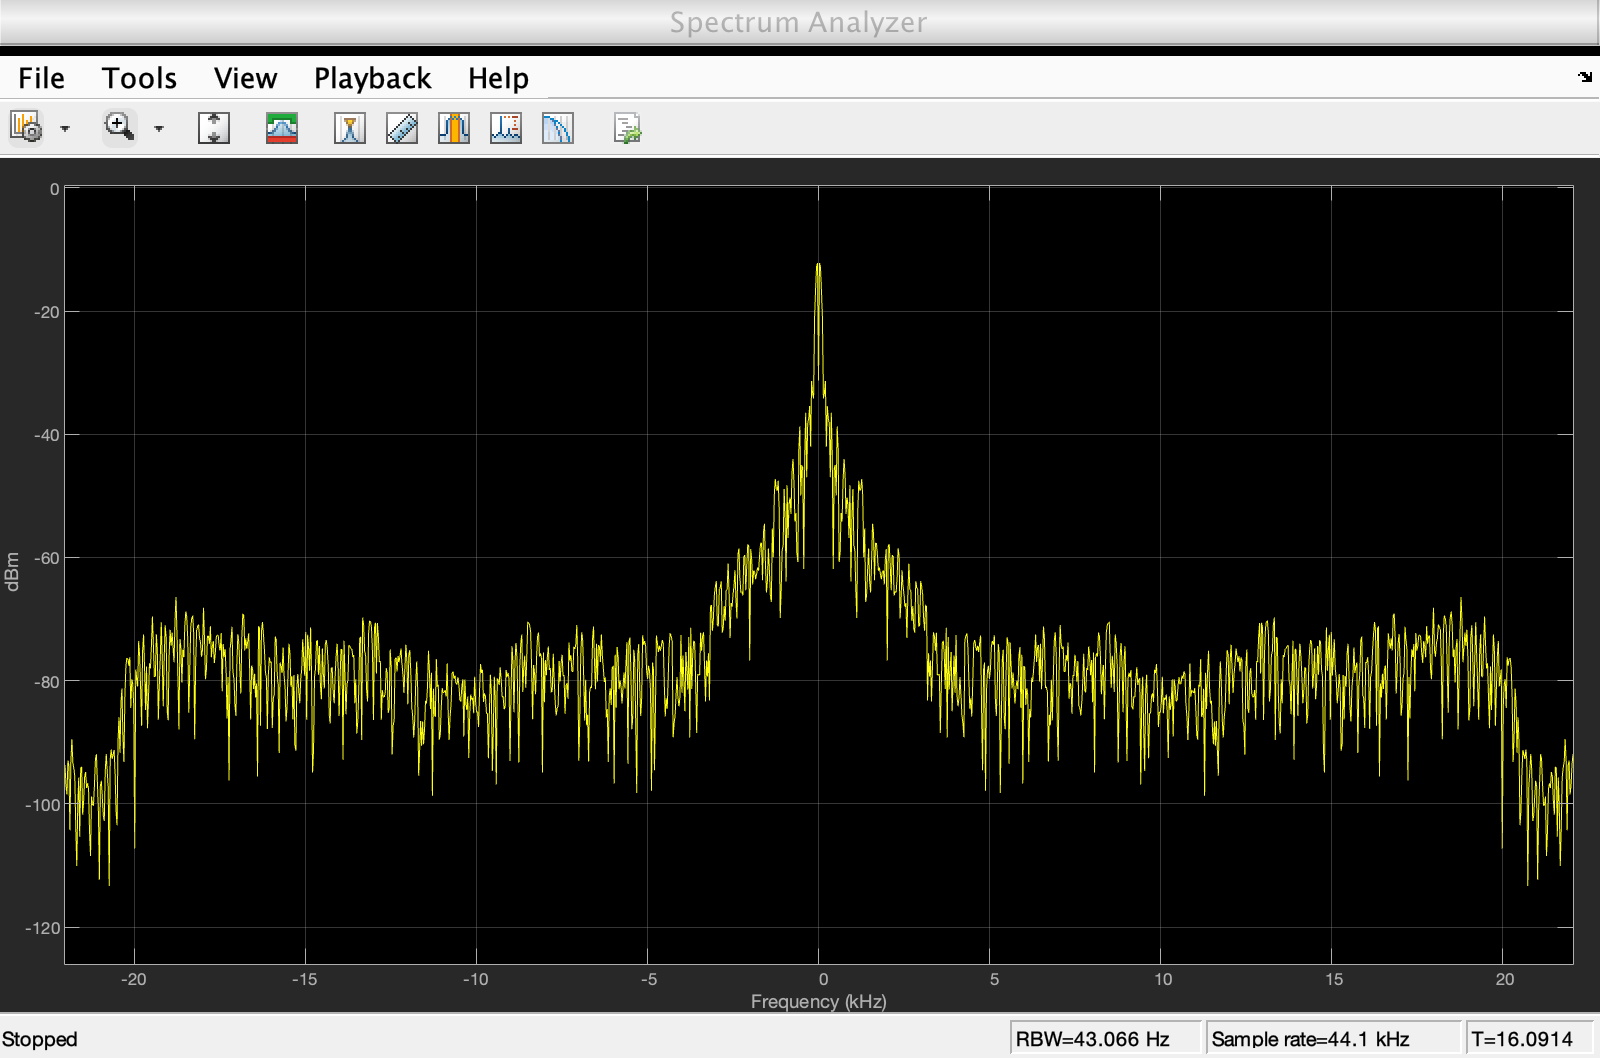


%% Create and Initialize
SamplesPerFrame = 1024;
Fs = 44100;
Microphone= audioDeviceReader('SamplesPerFrame', SamplesPerFrame);
Spectra= dsp.SpectrumAnalyzer('SampleRate',Fs);
%% Stream processing loop
tic;
while toc < 20
% Read frame from microphone
audioIn=step (Microphone) ;
% View audio spectrum
step (Spectra, audioIn);
end

%% Terminate
release (Microphone)
release (Spectra)